# This code is for filtering electron Rmax


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv287p61eV_ke260_0001\Ada_PEPICO_hv287p61eV_ke260_0001_ana';
raw_data = IO.import_raw(dir);
addpath(genpath('E:\PhD\Adamantane_data\mdata'))
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_corrected = macro.convert.R_theta(data_corrected, mdata, 'det1')

Log: R, theta conversion performed on det1


data_corrected = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


% R_e.C1	= macro.filter.write_coincidence_condition(1, 'det1');
% R_e.type	        = 'continuous';
% R_e.data_pointer	= 'h.det1.R';
% R_e.translate_condition = 'AND';
% R_e.value		= [0; 20];
% 
% [e_filter, ~]	= macro.filter.conditions_2_filter(data_corrected, R_e);
% hit_filter_e = filter.events_2_hits_det(e_filter, data_corrected.e.raw(:,1), length(data_corrected.h.det1.X),...
%     R_e, data_corrected); 
% hit_filter_i = filter.events_2_hits_det(e_filter, data_corrected.e.raw(:,2), length(data_corrected.h.det2.X),...
%     R_e, data_corrected); 
% data_corrected.e.raw = data_corrected.e.raw(e_filter);
% 
% data_corrected.e.det1.filt.C0 = data_corrected.e.det1.filt.C0(e_filter);
% data_corrected.e.det1.filt.C1 = data_corrected.e.det1.filt.C1(e_filter);
% data_corrected.e.det1.filt.C2 = data_corrected.e.det1.filt.C2(e_filter);
% data_corrected.e.det1.filt.C3 = data_corrected.e.det1.filt.C3(e_filter);
% data_corrected.e.det1.filt.C4 = data_corrected.e.det1.filt.C4(e_filter);
% data_corrected.e.det1.mult = data_corrected.e.det1.mult(e_filter);
% 
% data_corrected.e.det2.filt.C0 = data_corrected.e.det2.filt.C0(e_filter);
% data_corrected.e.det2.filt.C1 = data_corrected.e.det2.filt.C1(e_filter);
% data_corrected.e.det2.filt.C2 = data_corrected.e.det2.filt.C2(e_filter);
% data_corrected.e.det2.filt.C3 = data_corrected.e.det2.filt.C3(e_filter);
% data_corrected.e.det2.filt.C4 = data_corrected.e.det2.filt.C4(e_filter);
% data_corrected.e.det2.mult = data_corrected.e.det2.mult(e_filter);
% 
% data_corrected.h.det1.raw = data_corrected.h.det1.raw(hit_filter_e);
% data_corrected.h.det1.X = data_corrected.h.det1.X(hit_filter_e);
% data_corrected.h.det1.Y = data_corrected.h.det1.Y(hit_filter_e);
% 
% data_corrected.h.det2.raw = data_corrected.h.det2.raw(hit_filter_i);
% data_corrected.h.det2.X = data_corrected.h.det2.X(hit_filter_i);
% data_corrected.h.det2.Y = data_corrected.h.det2.Y(hit_filter_i);
% data_corrected.h.det2.TOF = data_corrected.h.det2.TOF(hit_filter_i);
% 


mdata = md_all();
data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
Log: Background signal created for det2 on the signal(s) TOF,


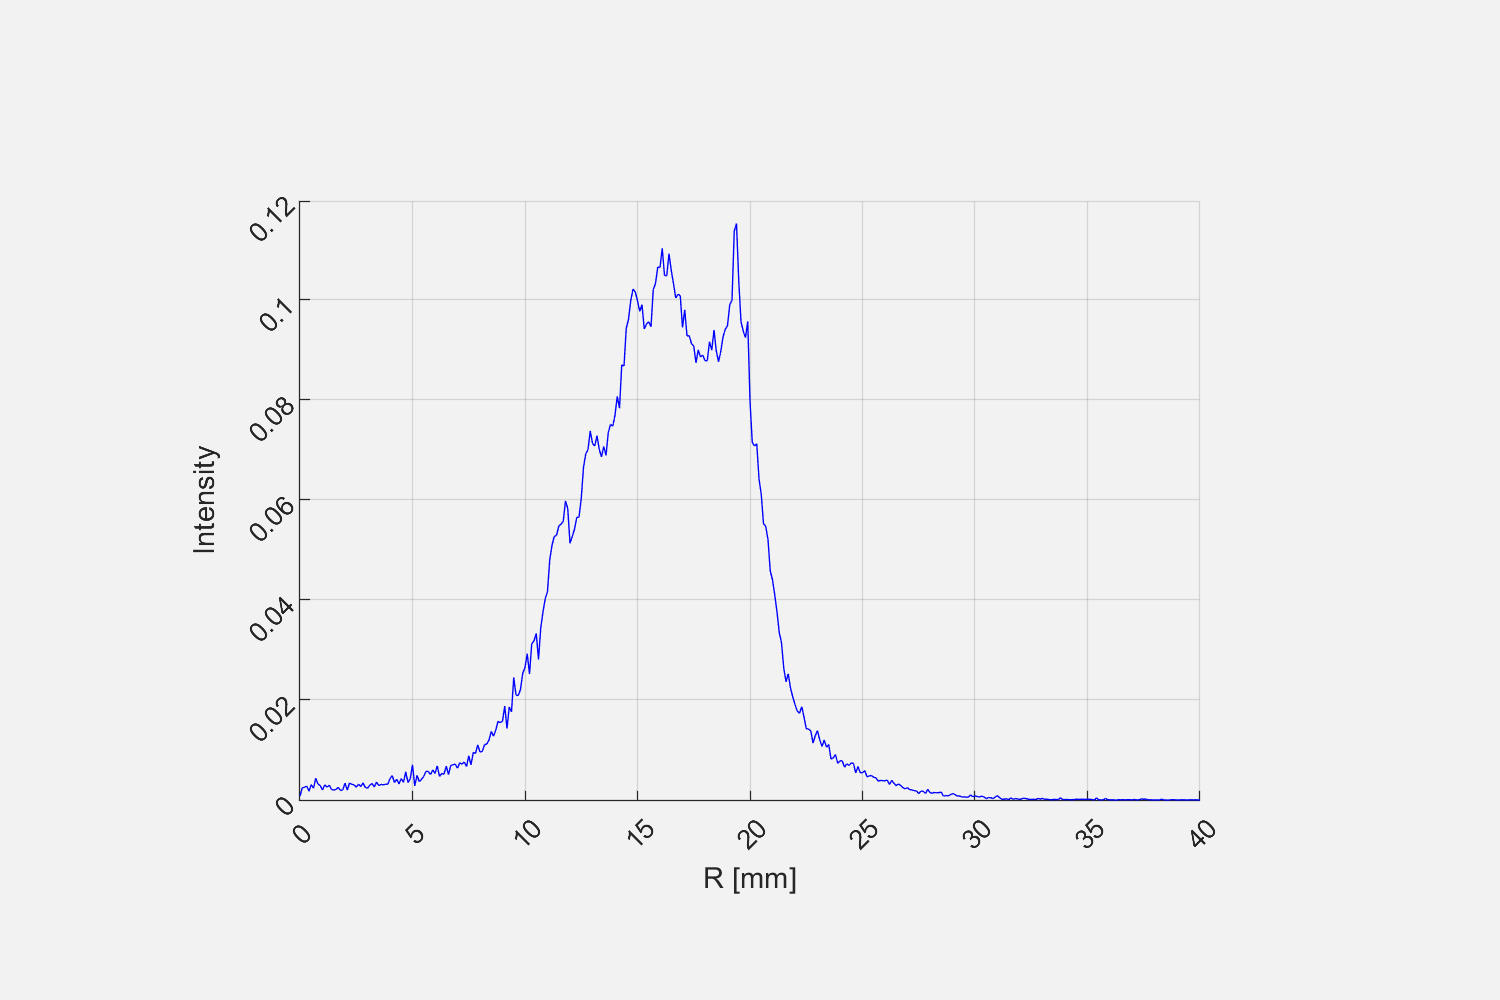

macro.plot(data_converted, mdata);

## Event statistics from all data

[data_stats] =get_data_stats(data_converted);

The Scaling factor is 0.96452


SC = data_stats.SC;
TP_0 =data_stats.TP_0;